1. Load ảnh cameraman

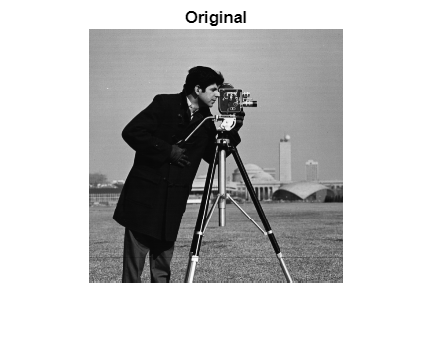

I = imread('cameraman.tif');

figure;
imshow(I); title("Original");

2. Thêm nhiễu salt & pepper (50%)

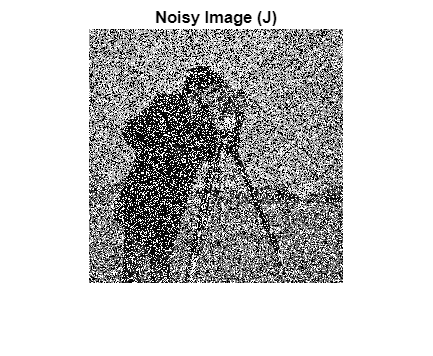

J = imnoise(I, 'salt & pepper', 0.5);

figure;
imshow(J); title("Noisy Image (J)");

3. Edge detection

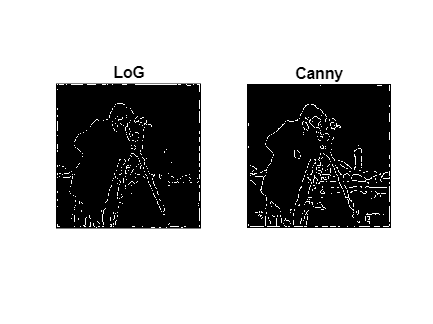

J_med = medfilt2(J, [8 8]);

% LoG
E1 = edge(J_med, 'log');

% Canny
E2 = edge(J_med, 'canny');

figure;
subplot(1,2,1); imshow(E1); title("LoG");
subplot(1,2,2); imshow(E2); title("Canny")

4. Median filter with window size = 8x8

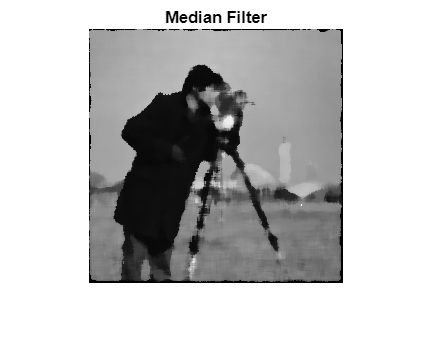

% Median filter (8x8)
J_med = medfilt2(J, [8 8]);

figure;
imshow(J_med); title("Median Filter");

5. Kết hợp ảnh khử nhiễu

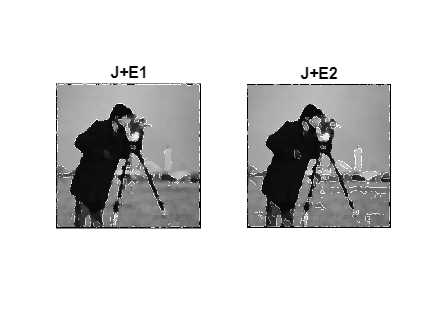

alpha = 0.4;
J_E1 = imadd(J_med, uint8(alpha * double(E1) * 255));
J_E2 = imadd(J_med, uint8(alpha * double(E2) * 255));

figure;
subplot(1,2,1); imshow(J_E1); title("J+E1");
subplot(1,2,2); imshow(J_E2); title("J+E2")